# Decision Making Algorithm - Active & Passive Data

#### This script performs a user defined threshold check on two data inputs (SNR_input_1 & SNR_input_2).  SNR_input_1 is the preferred data source (i.e., Passive).  If SNR_input_1 data is => the threshold, this value is selected, if not the same check is completed on SNR_inpupt_2, if this meets the threshold then this value is selected. If both data sets do not meet the threshold the highest value is selected.

#### A counter increments each time an input is selected. The best case values are also stored for visualisation.

#### The result is output in total counts and the percentage of time each input was chosen.

#### The data is also visualised in a plot, a scatter and a hybrid plot-scatter. 

# Thresholding with Baseline Data

User to define the data inputs for comparison

SNR_input_1 = passive_SNR;
SNR_input_2 = active_SNR;

Visualisation of Active & Passive SNR

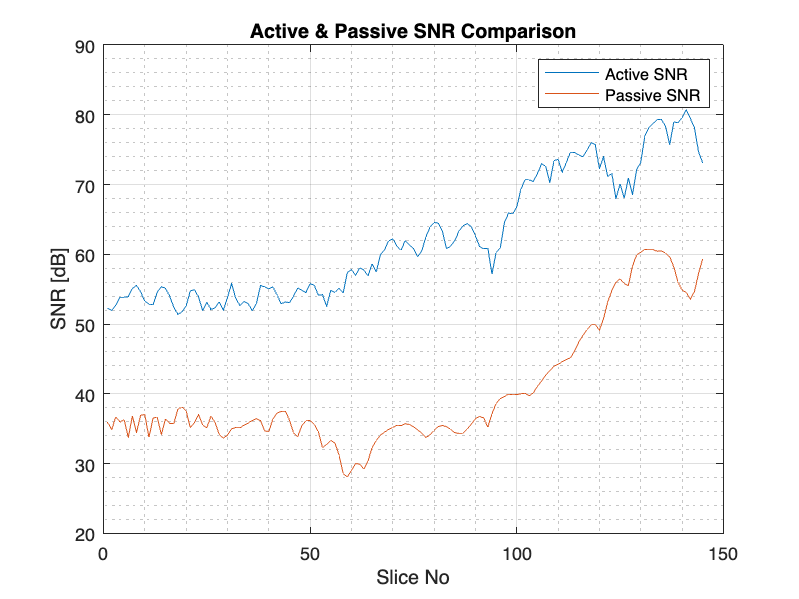

figure
% figure_title = ('Active & Passive SNR Comparison');
fig = figure;
plot(1:length(active_SNR), active_SNR, 'LineWidth', 0.5)
hold on
plot(1:length(passive_SNR), passive_SNR, 'LineWidth', 0.5)
hold off
% plot(1:length(active_SNR), active_SNR, ...
%     1:length(passive_SNR), passive_SNR, 'LineWidth', 2)
title('Active & Passive SNR Comparison');
ylabel('SNR [dB]');
xlabel('Slice No') ;
legend("Active SNR", 'Passive SNR')
grid on
%ylim([-max_doppler max_doppler]); % Doppler Limit
% xlim([-inf length(passive_SNR)]);   % Range Limit
grid minor

Introduce Decision Making

% Desired threshold
threshold = 40;

% Initialize a cell array to store the results
if length(SNR_input_1) == length(SNR_input_2)
    selected_input_value = zeros(1,length(SNR_input_1));
    selected_input_id = zeros(1,length(SNR_input_2));
    count_input_1 = 0;
    count_input_2 = 0;
else
    error('Inputs are not the same length.')
end

% Loop through each cell entry
for i = 1:length(SNR_input_1)
    % Threshold check for each cell entry
    if SNR_input_1(i) >= threshold
        selected_input_value(i) = SNR_input_1(i); % stores the value [dB]
        selected_input_id(i) = 1; % stores the input ID
        count_input_1 = count_input_1 + 1;
        % disp(['Input 1 selected for cell ' num2str(i) '.']);
    elseif SNR_input_2(i) >= threshold
        selected_input_value(i) = SNR_input_2(i); % stores the value [dB]
        selected_input_id(i) = 2; % stores the input ID
        count_input_2 = count_input_2 + 1;
        % disp(['Input 2 selected for cell ' num2str(i) '.']);
    else
        if SNR_input_1(i) > SNR_input_2(i)
            selected_input_value(i) = SNR_input_1(i); % stores the value [dB]
            selected_input_id(i) = 1; % stores the input ID
            count_input_1 = count_input_1 + 1;
            % disp(['Threshold not met. Input 1 selected for cell ' num2str(i) '.']);
        else
            selected_input_value(i) = SNR_input_2(i); % stores the value [dB]
            selected_input_id(i) = 2; % stores the input ID
            count_input_2 = count_input_2 + 1;
            % disp(['Threshold not met. Input 2 selected for cell ' num2str(i) '.']);
        end
    end
end

Result in Numbers

count_input_1

count_input_1 = 43

count_input_2

count_input_2 = 102

percent_usage_input_1 = (count_input_1 / length(SNR_input_1))*100

percent_usage_input_1 = 29.6552

percent_usage_input_2 = (count_input_2 / length(SNR_input_2))*100

percent_usage_input_2 = 70.3448

## Visualisation of Active, Passive & Threshold decision SNR

As a plot

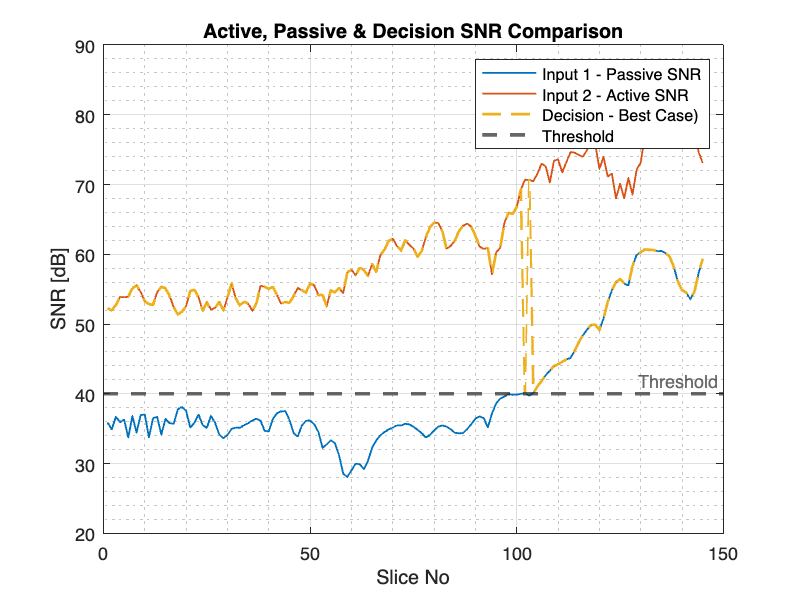

figure
% figure_title = ('Active & Passive SNR Comparison');
fig = figure;
% plot(1:length(active_SNR), active_SNR, ...
%     1:length(passive_SNR), passive_SNR, ...
%     1:length(selected_input_value), selected_input_value)
plot(1:length(SNR_input_1), SNR_input_1, 'LineWidth', 1)
hold on
plot(1:length(SNR_input_2), SNR_input_2, 'LineWidth', 1)
plot(1:length(selected_input_value), selected_input_value, '--', 'LineWidth', 1.5)

title('Active, Passive & Decision SNR Comparison');
ylabel('SNR [dB]');
xlabel('Slice No') ;
legend("Active SNR", 'Passive SNR', 'Decision (best case)')
grid on
%ylim([-max_doppler max_doppler]); % Doppler Limit
% xlim([-inf length(passive_SNR)]);   % Range Limit
grid minor
hold on

% Plot the threshold line
threshold_line = yline(threshold, '--', 'Threshold', 'LineWidth', 2);
legend("Input 1 - Passive SNR", 'Input 2 - Active SNR', 'Decision - Best Case)', 'Threshold')
hold off


sum(selected_input_id);


As a Scatter

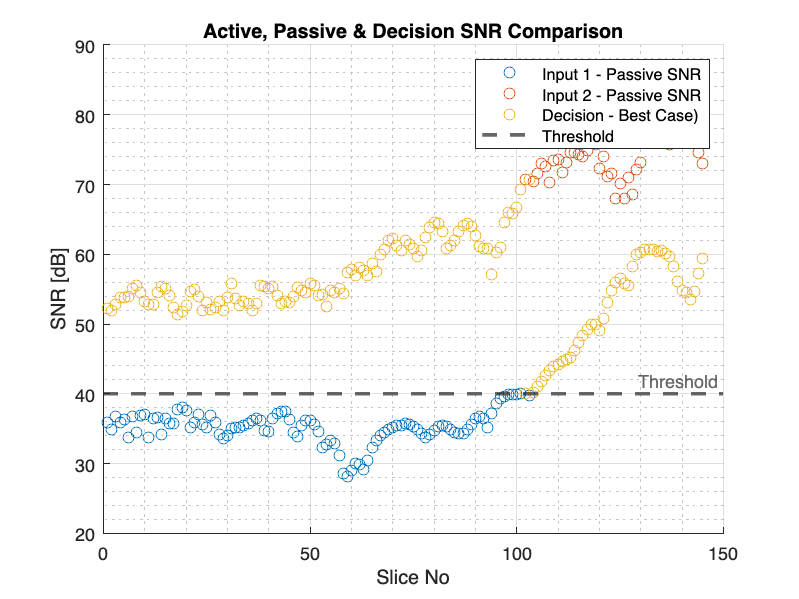

figure
scatter(1:length(SNR_input_1), SNR_input_1, 'LineWidth', 0.5)
hold on
scatter(1:length(SNR_input_2), SNR_input_2, 'LineWidth', 0.5)
scatter(1:length(selected_input_value), selected_input_value, 'LineWidth', 0.5)

title('Active, Passive & Decision SNR Comparison');
ylabel('SNR [dB]');
xlabel('Slice No') ;
legend("Active SNR", 'Passive SNR', 'Decision (best case)')
grid on
%ylim([-max_doppler max_doppler]); % Doppler Limit
% xlim([-inf length(passive_SNR)]);   % Range Limit
grid minor
hold on

% Plot the threshold line
threshold_line = yline(threshold, '--', 'Threshold', 'LineWidth', 2);
legend("Input 1 - Passive SNR", 'Input 2 - Passive SNR', 'Decision - Best Case)', 'Threshold')
hold off

As a hybrid Scatter

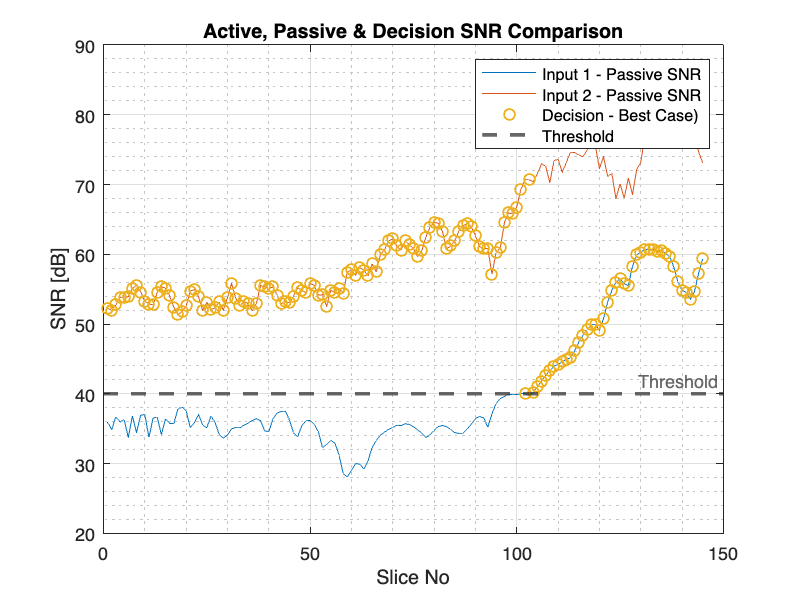

figure
plot(1:length(SNR_input_1), SNR_input_1, 'LineWidth', 0.5)
hold on
plot(1:length(SNR_input_2), SNR_input_2, 'LineWidth', 0.5)
scatter(1:length(selected_input_value), selected_input_value, 'LineWidth', 1)

title('Active, Passive & Decision SNR Comparison');
ylabel('SNR [dB]');
xlabel('Slice No') ;
legend("Active SNR", 'Passive SNR', 'Decision (best case)')
grid on
%ylim([-max_doppler max_doppler]); % Doppler Limit
% xlim([-inf length(passive_SNR)]);   % Range Limit
grid minor
hold on

% Plot the threshold line
threshold_line = yline(threshold, '--', 'Threshold', 'LineWidth', 2);
legend("Input 1 - Passive SNR", 'Input 2 - Passive SNR', 'Decision - Best Case)', 'Threshold')
hold off

# Thresholding with Noisy Data (Bespoke Noise Generator Data)

Visualise SNR data options.

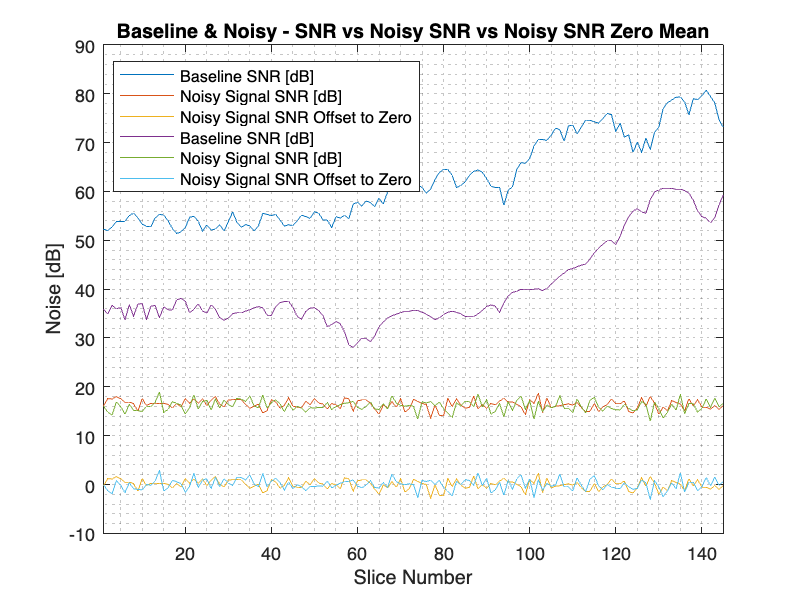

figure;
fig = figure;
plot(1:length(active_SNR), active_SNR, ...
    1:length(noisy_active_SNR), noisy_active_SNR, ...
    1:length(noisy_active_SNR_dB_zeroed), noisy_active_SNR_dB_zeroed, ...
    1:length(passive_SNR), passive_SNR, ...
    1:length(noisy_passive_SNR), noisy_passive_SNR, ...
    1:length(noisy_passive_SNR_dB_zeroed), noisy_passive_SNR_dB_zeroed)
% yline(active_mean_active_SNR_dB, '--', ...
%     ['Baseline SNR Mean: ' num2str(active_mean_active_SNR_dB)], ...
%     'LineWidth', 0.25, ...
%     'FontSize', 6);
% yline(active_mean_noisy_active_SNR_dB, '--', ...
%     ['Noisy SNR Mean: ' num2str(active_mean_noisy_active_SNR_dB)], ...
%     'LineWidth', 0.25, ...
%     'FontSize', 6);
legend( 'Baseline SNR [dB]', ...
    'Noisy Signal SNR [dB]', ...
    'Noisy Signal SNR Offset to Zero', ...
    'Baseline SNR [dB]', ...
    'Noisy Signal SNR [dB]', ...
    'Noisy Signal SNR Offset to Zero', ...
    'location', 'best')
grid minor
title('Baseline & Noisy - SNR vs Noisy SNR vs Noisy SNR Zero Mean');
ylabel('Noise [dB]');
xlabel('Slice Number');
xlim([1, length(noisy_active_SNR)])

Save figure to repo

% fig_name = figure_directory + bracket + inputstructure.name + ' Signal Peak subplots - Range Vs Slice and Doppler Vs Slice';
% savefig(figure_title)
% saveas(fig, fig_name + '.png')

Define SNR_input_1 & SNR_input_2

SNR_input_1 = noisy_passive_SNR_dB_zeroed; % preferred input, i.e. passive
SNR_input_2 = noisy_active_SNR_dB_zeroed;

Visualisation of Active & Passive SNR

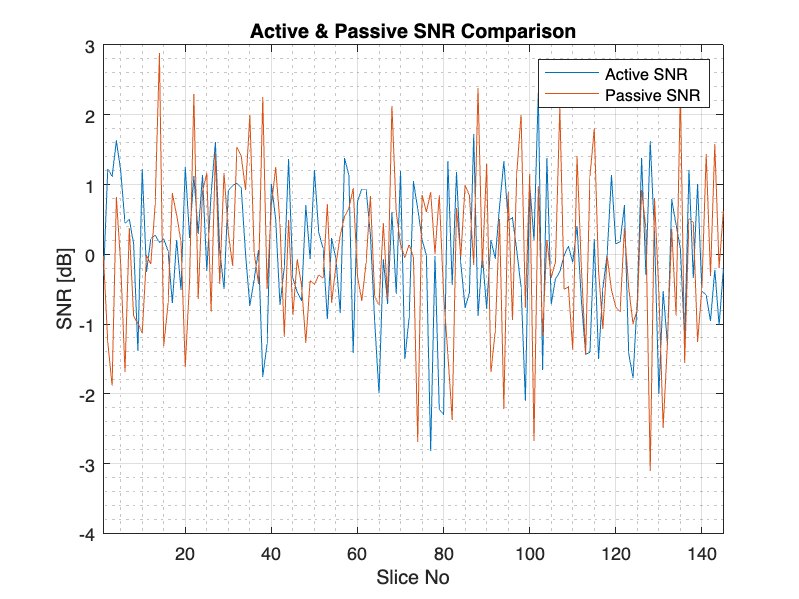

figure
% figure_title = ('Active & Passive SNR Comparison');
fig = figure;
plot(1:length(SNR_input_2), SNR_input_2, 'LineWidth', 0.5) % Active data
hold on
plot(1:length(SNR_input_1), SNR_input_1, 'LineWidth', 0.5) % Passive data
hold off
% plot(1:length(active_SNR), active_SNR, ...
%     1:length(passive_SNR), passive_SNR, 'LineWidth', 2)
title('Active & Passive SNR Comparison');
ylabel('SNR [dB]');
xlabel('Slice No') ;
legend("Active SNR", 'Passive SNR')
grid on
%ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([1, length(SNR_input_1)])
grid minor

Introduce Decision Making

% Desired threshold
threshold = 0;

% Initialize a cell array to store the results
if length(SNR_input_1) == length(SNR_input_2)
    selected_input_value = zeros(1,length(SNR_input_1));
    selected_input_id = zeros(1,length(SNR_input_2));
    count_input_1 = 0;
    count_input_2 = 0;
else
    error('Inputs are not the same length.')
end

% Loop through each cell entry
for i = 1:length(SNR_input_1)
    % Threshold check for each cell entry
    if SNR_input_1(i) >= threshold
        selected_input_value(i) = SNR_input_1(i); % stores the value [dB]
        selected_input_id(i) = 1; % stores the input ID
        count_input_1 = count_input_1 + 1;
        % disp(['Input 1 selected for cell ' num2str(i) '.']);
    elseif SNR_input_2(i) >= threshold
        selected_input_value(i) = SNR_input_2(i); % stores the value [dB]
        selected_input_id(i) = 2; % stores the input ID
        count_input_2 = count_input_2 + 1;
        % disp(['Input 2 selected for cell ' num2str(i) '.']);
    else
        if SNR_input_1(i) > SNR_input_2(i)
            selected_input_value(i) = SNR_input_1(i); % stores the value [dB]
            selected_input_id(i) = 1; % stores the input ID
            count_input_1 = count_input_1 + 1;
            % disp(['Threshold not met. Input 1 selected for cell ' num2str(i) '.']);
        else
            selected_input_value(i) = SNR_input_2(i); % stores the value [dB]
            selected_input_id(i) = 2; % stores the input ID
            count_input_2 = count_input_2 + 1;
            % disp(['Threshold not met. Input 2 selected for cell ' num2str(i) '.']);
        end
    end
end

Result in Numbers

count_input_1 % Passive

count_input_1 = 92

count_input_2 % Active

count_input_2 = 53

percent_usage_input_1 = (count_input_1 / length(SNR_input_1))*100

percent_usage_input_1 = 63.4483

percent_usage_input_2 = (count_input_2 / length(SNR_input_2))*100

percent_usage_input_2 = 36.5517

## Visualisation of Active, Passive & Threshold decision SNR

As a plot

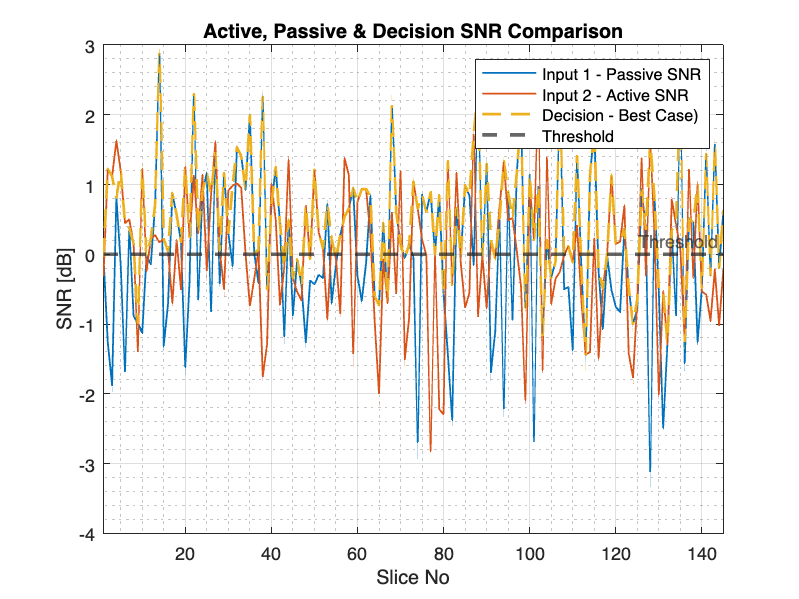

figure
% figure_title = ('Active & Passive SNR Comparison');
fig = figure;
% plot(1:length(active_SNR), active_SNR, ...
%     1:length(passive_SNR), passive_SNR, ...
%     1:length(selected_input_value), selected_input_value)
plot(1:length(SNR_input_1), SNR_input_1, 'LineWidth', 1)
hold on
plot(1:length(SNR_input_2), SNR_input_2, 'LineWidth', 1)
hold on
plot(1:length(selected_input_value), selected_input_value, '--', 'LineWidth', 1.5)

title('Active, Passive & Decision SNR Comparison');
ylabel('SNR [dB]');
xlabel('Slice No') ;
legend("Active SNR", 'Passive SNR', 'Decision (best case)')
grid on
%ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([1, length(SNR_input_1)]);   % Range Limit
grid minor
hold on

% Plot the threshold line
threshold_line = yline(threshold, '--', 'Threshold', 'LineWidth', 2);
legend("Input 1 - Passive SNR", 'Input 2 - Active SNR', 'Decision - Best Case)', 'Threshold')
hold off

As a Scatter

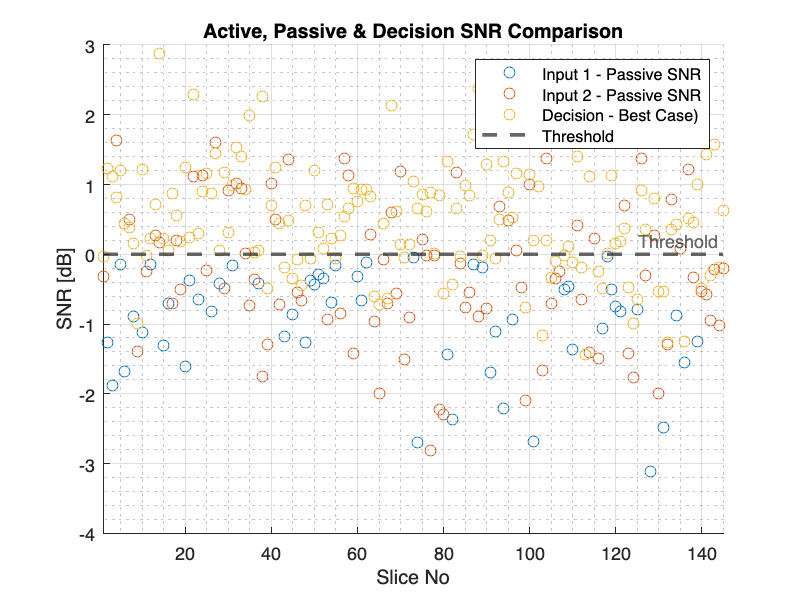

figure
scatter(1:length(SNR_input_1), SNR_input_1, 'LineWidth', 0.5)
hold on
scatter(1:length(SNR_input_2), SNR_input_2, 'LineWidth', 0.5)
hold on
scatter(1:length(selected_input_value), selected_input_value, 'LineWidth', 0.5)

title('Active, Passive & Decision SNR Comparison');
ylabel('SNR [dB]');
xlabel('Slice No') ;
legend("Active SNR", 'Passive SNR', 'Decision (best case)')
grid on
%ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([1, length(SNR_input_1)]);   % Range Limit
grid minor
hold on

% Plot the threshold line
threshold_line = yline(threshold, '--', 'Threshold', 'LineWidth', 2);
legend("Input 1 - Passive SNR", 'Input 2 - Passive SNR', 'Decision - Best Case)', 'Threshold')
hold off

As a hybrid Scatter

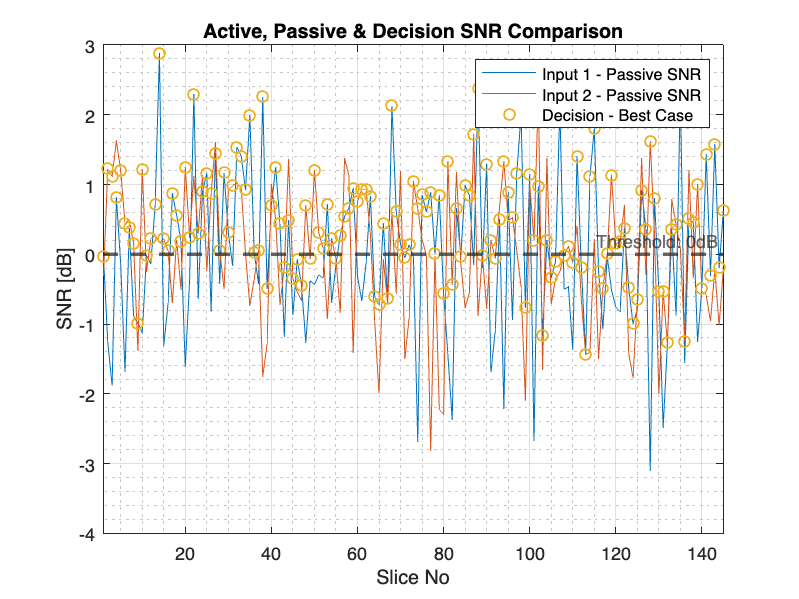

figure
plot(1:length(SNR_input_1), SNR_input_1, 'LineWidth', 0.5)
hold on
plot(1:length(SNR_input_2), SNR_input_2, 'LineWidth', 0.5)
hold on
scatter(1:length(selected_input_value), selected_input_value, 'LineWidth', 1)

title('Active, Passive & Decision SNR Comparison');
ylabel('SNR [dB]');
xlabel('Slice No') ;
% legend("Active SNR", 'Passive SNR', 'Decision (best case)', '')
grid on
%ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([1, length(SNR_input_1)]);   % Range Limit
grid minor
hold on

% Plot the threshold line
threshold_line = yline(threshold, '--', ['Threshold: ' num2str(threshold) 'dB'], 'LineWidth', 2);
legend("Input 1 - Passive SNR", ...
    'Input 2 - Passive SNR', ...
    'Decision - Best Case', '')
hold off

# Metrics

Min, Mean and Max of SNR_input_1, SNR_input_2 & the Hydrid (result of the thresholding)

SNR_input_1 (passive):

min_snr_input_1 = min(SNR_input_1); % [dB]
mean_snr_input_1 = mean(SNR_input_1); % [dB]
max_snr_input_1 = max(SNR_input_1); % [dB]

SNR_input_2 (active):

min_snr_input_2 = min(SNR_input_2); % [dB]
mean_snr_input_2 = mean(SNR_input_2); % [dB]
max_snr_input_2 = max(SNR_input_2); % [dB]

selected_input_value (hybrid):

min_snr_hybrid = min(selected_input_value); % [dB]
mean_snr_hydrid = mean(selected_input_value); % [dB]
max_snr_hybrid = max(selected_input_value); % [dB]

Display results:

disp(['Passive SNR Min: ' num2str(min_snr_input_1)]);

Passive SNR Min: -3.1096


disp(['Active SNR Min: ' num2str(min_snr_input_2)]);

Active SNR Min: -2.8156


disp(['Hydrid SNR Min: ' num2str(min_snr_hybrid)]);

Hydrid SNR Min: -1.4332



disp(['Passive SNR Mean: ' num2str(mean_snr_input_1)]);

Passive SNR Mean: 8.698e-16


disp(['Active SNR Mean: ' num2str(mean_snr_input_2)]);

Active SNR Mean: -3.7732e-15


disp(['Hydrid SNR Mean: ' num2str(mean_snr_hydrid)]);

Hydrid SNR Mean: 0.50746



disp(['Passive SNR Max: ' num2str(max_snr_input_1)]);

Passive SNR Max: 2.8737


disp(['Active SNR Max: ' num2str(max_snr_input_2)]);

Active SNR Max: 2.312


disp(['Hydrid SNR Max: ' num2str(max_snr_hybrid)]);

Hydrid SNR Max: 2.8737


Bar Chart:

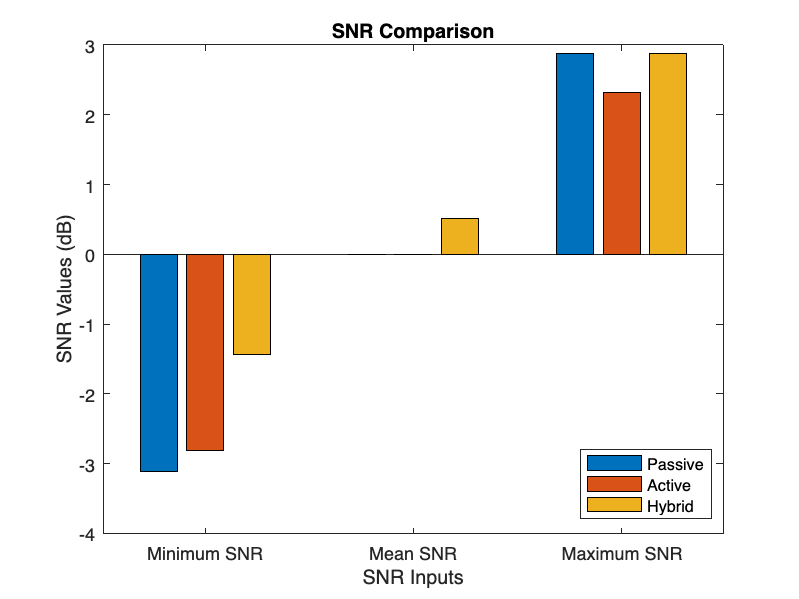

% Grouping data for bar chart
min_values = [min_snr_input_1, min_snr_input_2, min_snr_hybrid];
mean_values = [mean_snr_input_1, mean_snr_input_2, mean_snr_hydrid];
max_values = [max_snr_input_1, max_snr_input_2, max_snr_hybrid];

% Creating a grouped bar chart
figure;
fig = figure;
bar([min_values; mean_values; max_values]);
title('SNR Comparison');
xlabel('SNR Inputs');
ylabel('SNR Values (dB)');
legend('Passive', 'Active', 'Hybrid', 'Location', 'best');
set(gca, 'XTickLabel', {'Minimum SNR', 'Mean SNR', 'Maximum SNR'});

Box Plot:

`boxplot(`[`x`](https://www.mathworks.com/help/releases/R2023b/stats/boxplot.html?doclanguage=en&nocookie=true&prodfilter=ML%20SL%20CM%20DS%20AR%20RA%20RB%20RP%20RF%20SG%20ST&docviewer=helpbrowser&docrelease=R2023b&s_cid=pl_webdoc&loginurl=https%3A%2F%2F127.0.0.1%3A31515%2Ftoolbox%2Fmatlab%2Flogin%2Fweb%2Findex.html%3Fsnc%3DXXT6P6%26external%3Dtrue%26channel%3D__mlfpmc__&searchsource=mw&snc=5UA4KU&browser=F1help&container=jshelpbrowser#bu180jd-x)`)` creates a box plot of the data in `x`. If `x` is a vector, `boxplot` plots one box. If `x` is a matrix, `boxplot` plots one box for each column of `x`.

On each box, the central mark indicates the median, and the bottom and top edges of the box indicate the 25th and 75th percentiles, respectively. The whiskers extend to the most extreme data points not considered outliers, and the outliers are plotted individually using the `'+'` marker symbol.

The 25th and 75th percentiles, and the whiskers do not add value (?).

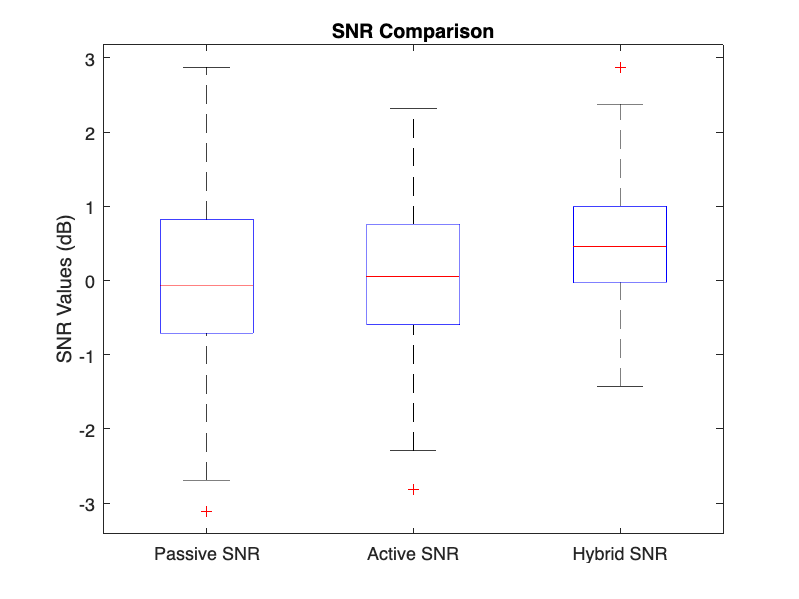

figure;
fig = figure;
boxplot([SNR_input_1', SNR_input_2', selected_input_value'], ...
    'Labels', {'Passive SNR', 'Active SNR', 'Hybrid SNR'});
title('SNR Comparison');
ylabel('SNR Values (dB)');

Metric Table:

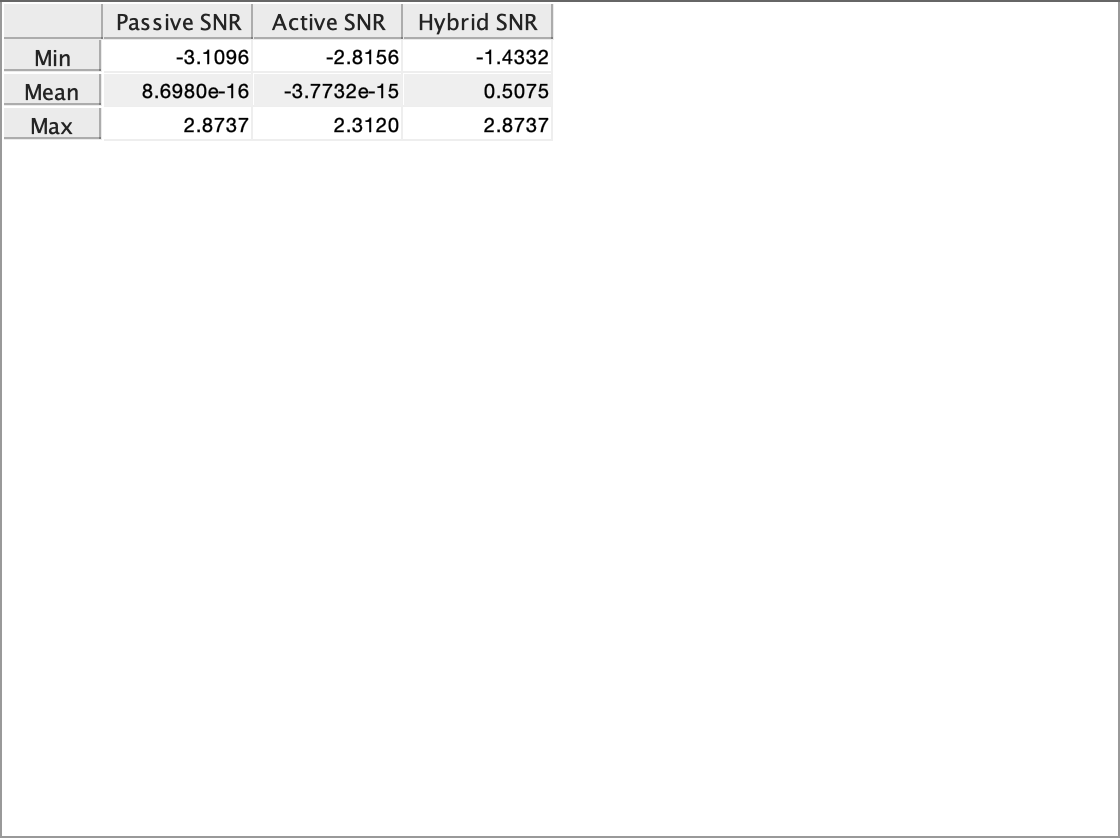

data = [min_snr_input_1, min_snr_input_2, min_snr_hybrid;
        mean_snr_input_1, mean_snr_input_2, mean_snr_hydrid;
        max_snr_input_1, max_snr_input_2, max_snr_hybrid];

rowNames = {'Min', 'Mean', 'Max'};
columnNames = {'Passive SNR', 'Active SNR', 'Hybrid SNR'};

resultTable = table(data(:, 1), data(:, 2), data(:, 3), 'VariableNames', columnNames, 'RowNames', rowNames);

% Create a figure and display the table
figure;
fig = figure;
uitable('Data', table2cell(resultTable), ...
    'RowName', resultTable.Properties.RowNames, ...
    'ColumnName', resultTable.Properties.VariableNames, ...
    'Units', 'Normalized', ...
    'Position', [0, 0, 1, 1]);


% Display the table
disp(resultTable);

            Passive SNR    Active SNR     Hybrid SNR
            ___________    ___________    __________

    Min        -3.1096         -2.8156     -1.4332  
    Mean     8.698e-16     -3.7732e-15     0.50746  
    Max         2.8737           2.312      2.8737  





disp(['Passive SNR Min: ' num2str(min_snr_input_1)]);

Passive SNR Min: -3.1096


disp(['Passive SNR Mean: ' num2str(mean_snr_input_1)]);

Passive SNR Mean: 8.698e-16


disp(['Passive SNR Max: ' num2str(max_snr_input_1)]);

Passive SNR Max: 2.8737



disp(['Active SNR Min: ' num2str(min_snr_input_2)]);

Active SNR Min: -2.8156


disp(['Active SNR Mean: ' num2str(mean_snr_input_2)]);

Active SNR Mean: -3.7732e-15


disp(['Active SNR Max: ' num2str(max_snr_input_2)]);

Active SNR Max: 2.312



disp(['Hydrid SNR Min: ' num2str(min_snr_hybrid)]);

Hydrid SNR Min: -1.4332


disp(['Hydrid SNR Mean: ' num2str(mean_snr_hydrid)]);

Hydrid SNR Mean: 0.50746


disp(['Hydrid SNR Max: ' num2str(max_snr_hybrid)]);

Hydrid SNR Max: 2.8737
